clear;
close all;

## Setup

% Values that we're giving you
Fs = 4e6; % Sampling rate (samples/sec)
Rs = 50e3; % Symbol rate in symbols/sec (baud)
Tmax = 0.1; % Max time for the simulation (sec)
fc = 1e6; % Carrier frequency (Hz)
B = 350e3; % Bandwidth (Hz)

% Complete these expressions using the variables above
N = Fs*Tmax; % Total number of sample points in the simulation
Ns = Rs*Tmax; % Number of symbols to send
sps = Fs/Rs; % Number of samples per symbol

% Use these variables for plotting
t = linspace(0, Tmax-1/Fs, N); % Time vector
f = linspace(-Fs/2, Fs/2, N); % Frequency vector. Recall from 113 that DFT gives us -f/2 to +f/2


## Symbol Generation

Generate random set of bits of 0s and 1s

bits = [0 1 0 0 0 0 1 1 0 1 1 0 1 1 1 1 0 1 1 0 1 1 1 0 0 1 1 0 0 1 1 1 0 1,... 
       1 1 0 0 1 0 0 1 1 0 0 0 0 1 0 1 1 1 0 1 0 0 0 1 1 1 0 0 1 1 0 0 1 0,...
       0 0 0 1 0 0 1 0 0 0 0 0 0 1 0 1 0 0 1 1 0 1 1 0 1 0 0 1 0 1 1 0 1 1,...
       0 1 0 1 1 1 0 1 0 1 0 1 1 0 1 1 0 0 0 1 1 0 0 0 0 1 0 1 1 1 0 1 0 0,...
       0 1 1 0 1 0 0 1 0 1 1 0 1 1 1 1 0 1 1 0 1 1 1 0 0 0 1 0 0 0 0 0 0 1,...
       1 0 1 0 0 1 0 1 1 1 0 0 1 1 0 0 1 0 0 0 0 0 0 1 1 0 0 0 1 1 0 1 1 0,...
       1 1 1 1 0 1 1 0 1 1 0 1 0 1 1 1 0 0 0 0 0 1 1 0 1 1 0 0 0 1 1 0 0 1,...
       0 1 0 1 1 1 0 1 0 0 0 1 1 0 0 1 0 1]; % "..." is line continuation

% Map bits to BPSK symbols of -1s and 1s
symbs = 2 * (bits - 0.5);


## Packet creation

% packet header = 3 keys
key = [1, 1, 1, -1, -1, -1, 1, -1, -1, 1, 1, -1, 1, -1, 1];
packet_header = repmat(key,1,3);

packet = cat(2, packet_header, symbs);
delay = 0 %round(normrnd(100, 5)) % in samples, (=0.25ms)

delay = 0

num_packets = fix((Ns-delay)/length(packet))

num_packets = 16

bits_remaining = rem((Ns-delay),length(packet))

bits_remaining = 184


transmit_symbs = [zeros(1, delay) repmat(packet,1,num_packets) zeros(1,bits_remaining)];
transmit_samps = upsample(transmit_symbs, sps);

figure
% stem(t,transmit_symbs, "DisplayName", "Delta train bits");
% xlim([0.001 0.003]);
% legend('show');
% Plot BPSK constellation digram
% figure
% scatterplot(symbs);
% title('BPSK Constellation Diagram');


## Carrier Modulation

% delta_train_symbs = upsample(symbs, sps);
% figure
% plot(t, delta_train_symbs, "DisplayName", "Delta train bits");
% xlim([0 0.001]);

rect_impulse = ones([1, sps]);
rect_filt = conv(transmit_samps, rect_impulse, "same");

roll_off =0.67;
span =10; % the number of symbols the impulse response of the RRC impulse response will last for
rrc_impulse = rcosdesign(roll_off, span, sps, "sqrt");
symb_wave = conv(transmit_samps, rrc_impulse, "same");

hold on
plot(t, symb_wave, "DisplayName", "RRC-filtered signal");

% Modulation
carrier = exp(-1i*2*pi*fc*t); % needed the 2*pi here
analytic_sig = carrier .* symb_wave;

ph_offset = 0;%unifrnd(0, 2*pi);
% select_ph_offset =0;
disp(["Phase: ", ph_offset]);

    "Phase: "    "0"



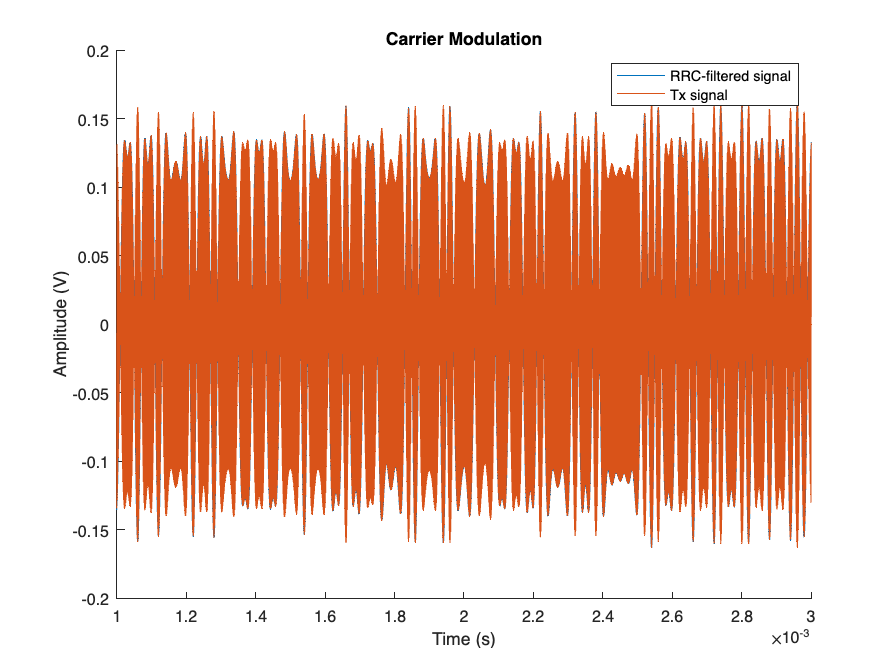

Tx = real(analytic_sig * exp(-1i*ph_offset));
hold on
plot(t, Tx, 'DisplayName', 'Tx signal');
xlim([0.001 0.003]);

title('Carrier Modulation');
xlabel('Time (s)');
ylabel('Amplitude (V)');
legend('show');

## Channel

channel_filter = "NONE";

if (channel_filter == "Tustin")
    s = tf('s');
    Hc = B*s/(s^2 + s*B + fc^2);
    Hd = c2d(Hc, 1/Fs, 'tustin');
    [a, b] = tfdata(Hd);
    Tx = real(filter(a{:}, b{:}, Tx));
else

end

is_noisy = false

is_noisy = logical
   0


if (is_noisy) 
% Gaussian noise
    std_dev =0.022;
    noise = std_dev * randn(1, N); %var = std_dev^2
    Rx = Tx + noise;
else
    Rx = Tx;
end

## Carrier Demodulation

Costas Loop

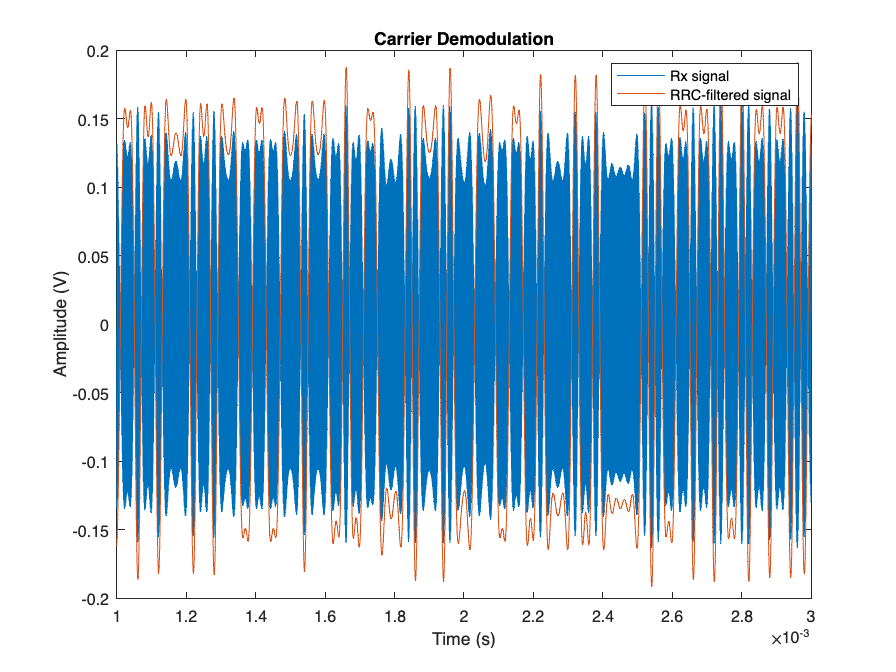

figure
plot(t, Rx, 'DisplayName', 'Rx signal'); 
xlim([0.001 0.003]);

inph = zeros(1, N);
quad = zeros(1, N);
inph_ = zeros(1, N);
quad_ = zeros(1, N);

err = zeros(1, N);
ph = zeros(1, N+1);

f_offset =0; %%%%%%%%%%%%%%%%%%%%%%%%%%%% CHANGING THIS...
fr = fc + f_offset; %2pi * fc/Fs

Kp =0.1;
Ki =0.001;
integrator = 0;

f = [0,0.2,0.4,1];
a = [1,1,0,0];
order = 5;
lp = firpm(order, f, a);
lp_length = length(lp);

% normalizeE?????

for idx =order+1:N

    nco_c = 2*cos(2*pi*fr*t(idx) + ph(idx));
    nco_s = -2*sin(2*pi*fr*t(idx) + ph(idx));

    % demodulate the signal by mixing with NCO signals
    inph_(idx) = Rx(idx) * nco_c;
    quad_(idx) = Rx(idx) * nco_s;

    % low pass filter to get rid of high frequency components
    I = filter(lp, 1, inph_(idx-order:idx));
    Q = filter(lp, 1, quad_(idx-order:idx));
    inph(idx) = I(end);
    quad(idx) = Q(end);

    % mix in_ph and quad to get error signal
    err(idx) = inph(idx)*quad(idx);

    % NCO
    integrator = integrator + Ki * err(idx);
    ph(idx+1) = ph(idx)+Kp*err(idx)+integrator;

end

%% Convolve with Receiver Impulse Response
rec_bb = inph + 1i * quad;
rec_bb = conv(rec_bb, rrc_impulse, 'same'); %%%%% why -
rec_samps = inph;
hold on;
plot(t, rec_samps, 'DisplayName', 'RRC-filtered signal');

% Now we're doing a smart downsampling instead
% hold on;
% rec_symbs = sign(real(rec_bb(1:sps:N))); %  downsampling
% plot(t, upsample(rec_symbs, sps), 'DisplayName', 'Received bits');
title('Carrier Demodulation');
xlabel('Time (s)');
ylabel('Amplitude (V)');
legend('show');

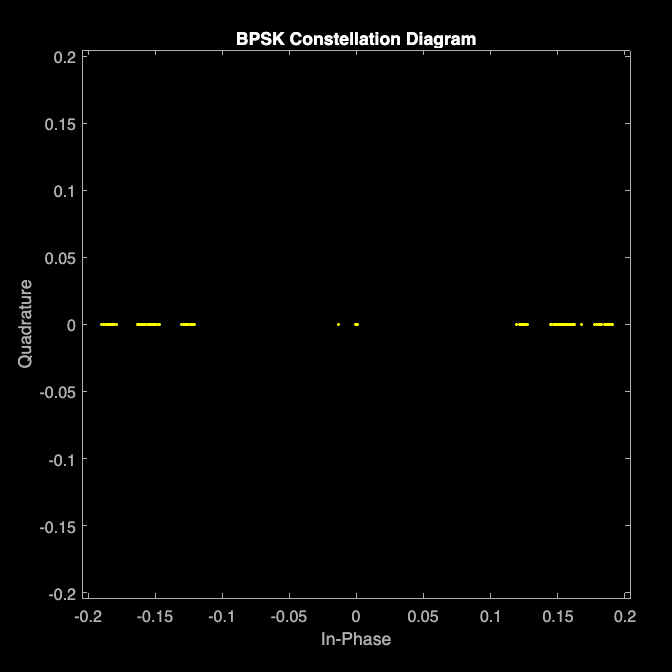


figure
scatterplot(rec_samps(1:sps:N)); %downsampling
% the points in the middle are due to the delay
title('BPSK Constellation Diagram');

## Symbol Detection

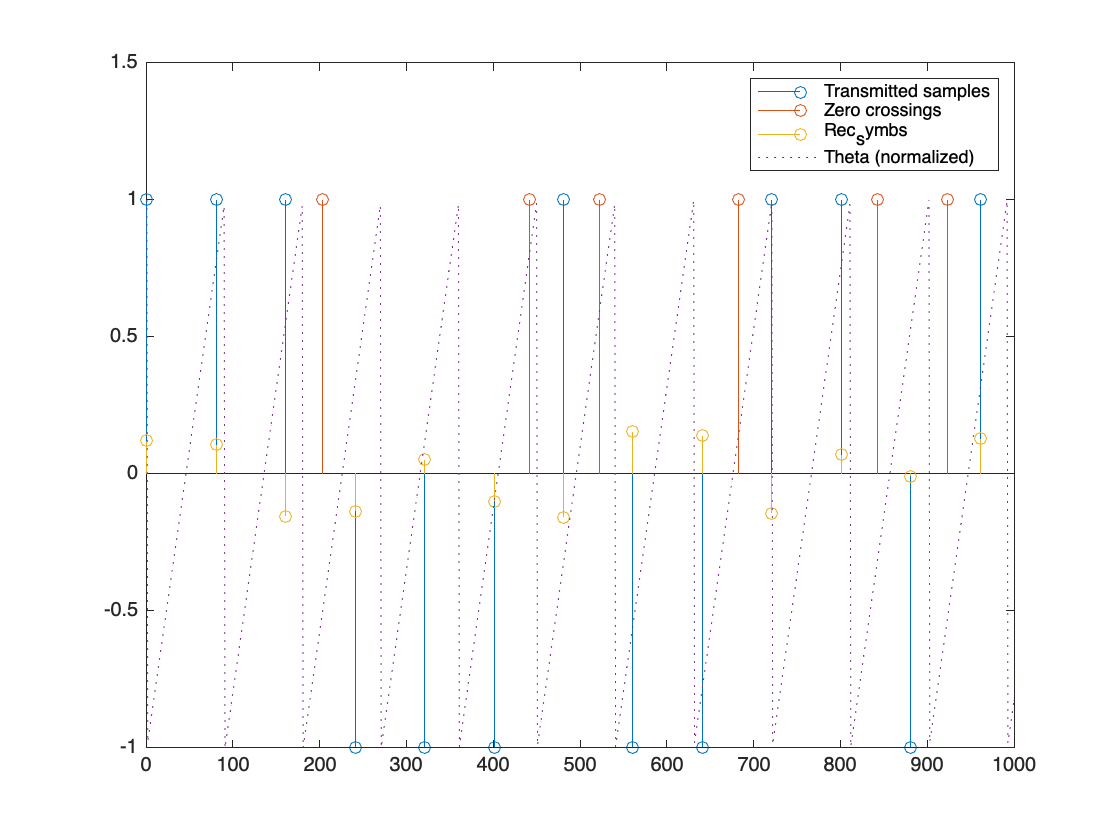

figure;
title('Symbol Detection');
x_max = 1000; %samples

plot_transmit_samps = transmit_samps;
plot_transmit_samps(plot_transmit_samps==0)=nan;
stem(plot_transmit_samps, 'DisplayName', 'Transmitted samples');
xlim([0 x_max]);

pair_products = sign(rec_samps(1:end-1).*rec_samps(2:end));
zero_crossings = ~(pair_products+1);
hold on;
plot_zero_crossings = double(zero_crossings);
plot_zero_crossings(plot_zero_crossings==0)=nan;
stem(plot_zero_crossings, 'DisplayName', 'Zero crossings');
xlim([0 x_max]);

% Packet synchronization
rec_symbs = zeros(1, Ns);
rec_symbs_idx = 1;

margin = 0.75;
err_sum = 0;
err = zeros(1, nnz(zero_crossings)); %only collect errors + guess_sps at zero_crossings
err_idx = 1;
guess_sps = zeros(1, nnz(zero_crossings));
current_sps_guess = 90; %80, which is what Tx
guess_sps(1) = current_sps_guess; %guess_sps only changes every time there is a zero crossing... idr like that

Kp = 0.1;
Ki = 0.00;

prev_theta = pi-0.0001; % to record the first sample. Not always beneficial ????
theta = zeros(1, N);
theta(1) = pi+0.0001; % want this to start at the first sample???

for idx=2:N %going around the circle, sample by sample
    theta(idx) = wrapToPi(theta(idx-1) + 2*pi/current_sps_guess); %not wrapTo2Pi because then error calc doesn't work out as nicely?
    
    if (wrapToPi(theta(idx)) < -pi*margin) && (wrapToPi(theta(idx-1)) > pi*margin)
        rec_symbs(rec_symbs_idx) = rec_samps(idx);
        rec_symbs_idx = rec_symbs_idx + 1;
    end
    
    if zero_crossings(idx-1)
        err(err_idx) = wrapToPi(theta(idx)); %something about the error calc is just wrong
        err_sum = err_sum + err(err_idx);
		guess_sps(err_idx+1) = guess_sps(err_idx) + Kp*err(err_idx) + Ki*err_sum;
        current_sps_guess = guess_sps(err_idx+1);
        
        err_idx = err_idx + 1;
    end

end

hold on;
upsampled_rec_symbs = upsample(rec_symbs,sps);
upsampled_rec_symbs(upsampled_rec_symbs==0)=nan;
stem(upsampled_rec_symbs, 'DisplayName', 'Rec_symbs');
xlim([0 x_max]);

plot(theta/pi,':', 'DisplayName', 'Theta (normalized)');
xlim([0 x_max]);
legend('show');

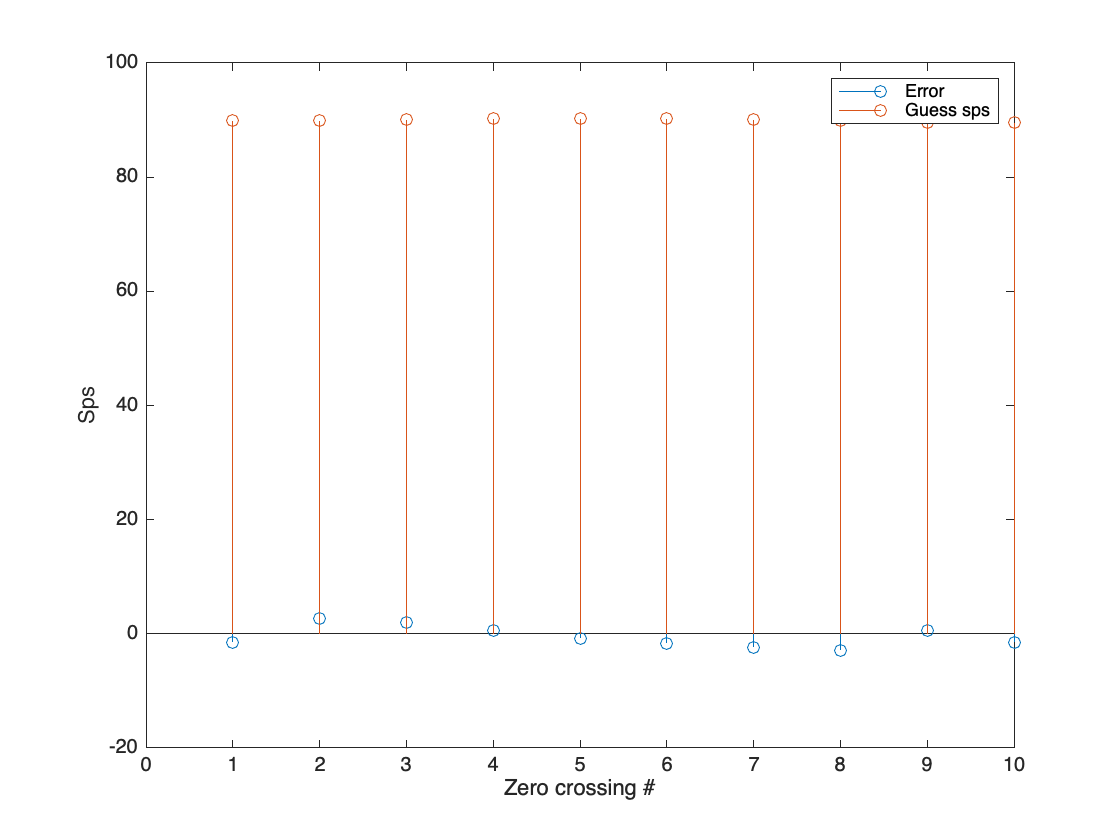

figure;
stem(err, 'DisplayName', 'Error');
hold on;
stem(guess_sps, 'DisplayName', 'Guess sps');
xlim([0 10]);
xlabel('Zero crossing #');
ylabel('Sps');
legend;

## Nathan's

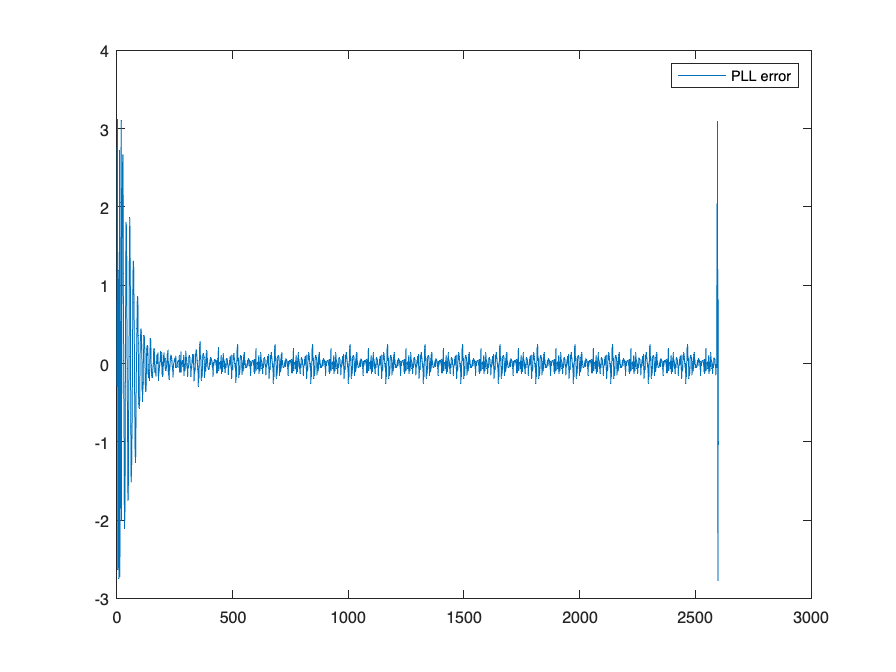

%PLL clock recovery pll
Kp_PLL = 0.3;
Ki_PLL = 1.1;
phase_acc = pi+0.00001;
prev_acc = pi-0.00001;
rec_samp = []; 
quad_samp=[];
err = [];
integrator = 70; %inte
for k = 1:N-1
  %Check if we have crossed zero on the phase accumulator
  %If the previous value was around -pi and the current value is around pi - we crossed it.
  if (wrapToPi(phase_acc )< -pi * 0.75 && wrapToPi(prev_acc) > pi*0.75)
    %we have crossed zero - sample
    rec_samp(end+1) = rec_samps(k);
%     quad_samp(end+1) = q(k);
  end
  %Detect zero crossing and use it to tune PLL
  if (zero_crossings(k))
    %we have a zero crossing - adjust freq
    err(end+1) = wrapToPi(phase_acc);
    integrator = integrator + err(end)*Ki_PLL;
    sps = err(end) * Kp_PLL + integrator;
  end
  prev_acc = phase_acc;
  phase_acc = phase_acc + 2*pi/sps;
end

figure;
plot(err);
legend("PLL error");

% rec_bits = (rec_symbs + 1)/2;
% bit_error = sum(abs(rec_bits - bits));
% bit_error_prob = bit_error/Ns
% 
% rec_samples = inph(1:sps:N);
% rec_bits = zeros([1, Ns]);
% for i=1:Ns
%     if (rec_samples(i) > 0); rec_bits(i) = 1; else; rec_bits(i) = 0; end
% end
% 
% total_err_plt = zeros(1, Ns);
% total_err = 0;
% for idx=1:Ns
%     if (rec_bits(idx) ~= bits(idx))
%         total_err = total_err + 1;
%     end
%     total_err_plt(idx) = total_err;
% end
% figure();
%plot(1:Ns, total_err_plt);


% err_rate = sum(rec_bits ~= bits) / Ns;